# Práctica Cinco

### Imagenes de Entrada

originalCircuit = im2gray(imread('Images/Circuito.tif'));
noisyGaussianCircuit = imnoise(originalCircuit,'gaussian',0,0.04);
noisySaltPepperCircuit = imnoise(originalCircuit,'salt & pepper',0.25);

originalLenna = im2gray(imread('Images/lenag.bmp'));
noisyGaussianLenna = imnoise(originalLenna,'gaussian',0,0.04);

### Implementación

#### Ejercicio Uno

Filtra la imagen primero con un filtro promedio aritmético de tamaño 3 × 3, y luego filtrala con un filtro promedio geométrico del mismo tamaño.  						

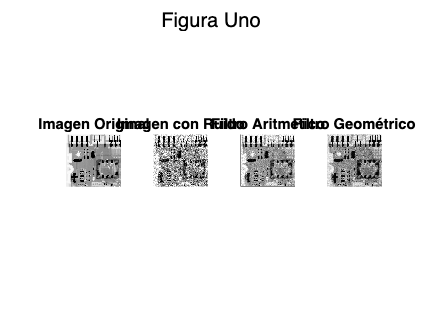

results01 = cell(1, 4);
results01{1,1} = originalCircuit;
results01{1,2} = noisyGaussianCircuit;
results01{1,3} = uint8(applyMedianFilter(noisyGaussianCircuit, 3, 'aritmetico'));
results01{1,4} = uint8(applyMedianFilter(noisyGaussianCircuit, 3, 'geometrico'));
showMultipleImages('Figura Uno', results01,{'Imagen Original','Imagen con Ruido', 'Filtro Aritmetico', 'Filtro Geométrico'}); 

#### Ejercicio Dos

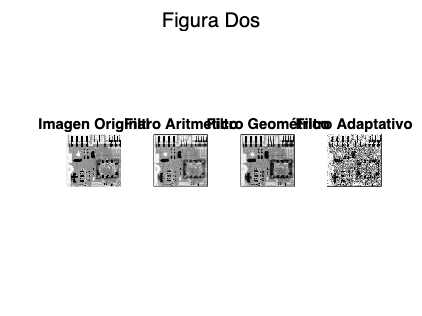

results02 = cell(1, 4);
results02{1,1} = originalCircuit;
results02{1,2} = uint8(applyMedianFilter(noisyGaussianCircuit, 7, 'aritmetico'));
results02{1,3} = uint8(applyMedianFilter(noisyGaussianCircuit, 7, 'geometrico'));
results02{1,4} = uint8(applyMedianFilter(noisyGaussianCircuit, 7, 'adaptativo'));
showMultipleImages('Figura Dos', results02,{'Imagen Original', 'Filtro Aritmetico', 'Filtro Geométrico', 'Filtro Adaptativo'}); 

#### Ejercicio Tres

Filtro mediana de tamanño 7 × 7. Filtrala ahora con un filtro mediana adaptativo con Smax = 7.  						 

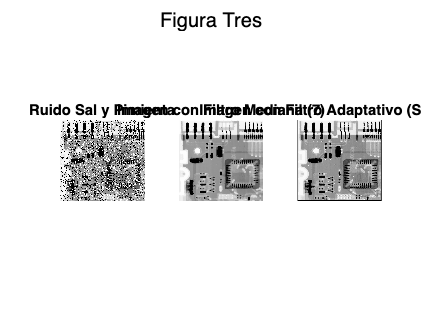

Smax = 7; 
results03 = cell(1, 3);
results03{1,1} = noisySaltPepperCircuit;
results03{1,2} = uint8(applyMedianFilter(noisySaltPepperCircuit, 7, 'aritmetico'));
results03{1,3} = adaptiveFilter(noisySaltPepperCircuit,Smax);
showMultipleImages('Figura Tres',results03,{'Ruido Sal y Pimienta', 'Imagen con Filtro Mediana (7)', 'Imagen con Filtro Adaptativo (Smax = 7)'});

#### Ejercicio Cuatro

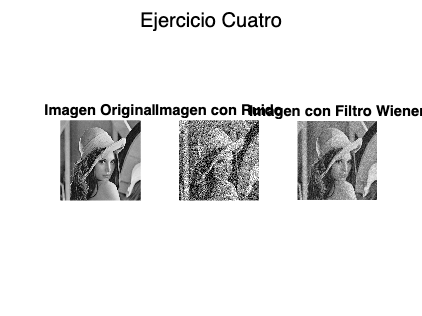

results04 = cell(1, 3);
results04{1,1} = originalLenna;
results04{1,2} = noisyGaussianLenna;
results04{1,3} = wiener(originalLenna,noisyGaussianLenna,1);
showMultipleImages('Ejercicio Cuatro',results04,{'Imagen Original', 'Imagen con Ruido', 'Imagen con Filtro Wiener'});

#### Ejercicio Cinco

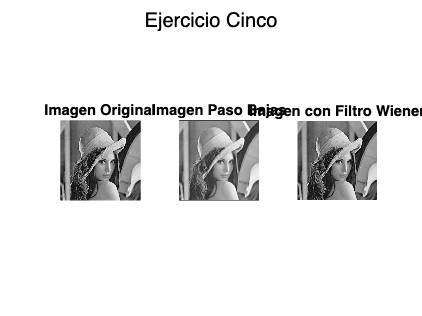

imagenPasoBajas = applyWeightedAverage(originalLenna,9);
results05 = cell(1, 3);
results05{1,1} = originalLenna;
results05{1,2} = imagenPasoBajas;
results05{1,3} = wiener(double(originalLenna),imagenPasoBajas,2);
showMultipleImages('Ejercicio Cinco',results05,{'Imagen Original', 'Imagen Paso Bajas', 'Imagen con Filtro Wiener'});

#### Ejercicio Seis

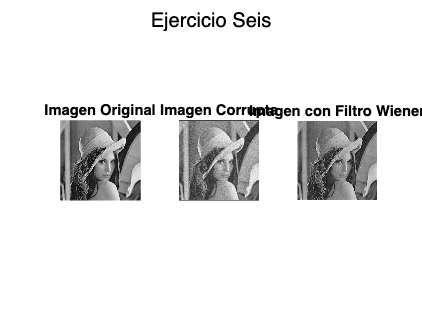

corruptedImage = applyWeightedAverage(noisyGaussianLenna,9);
results06 = cell(1, 3);
results06{1,1} = originalLenna;
results06{1,2} = corruptedImage;
results06{1,3} = wiener(double(originalLenna),corruptedImage,3);
showMultipleImages('Ejercicio Seis',results06,{'Imagen Original', 'Imagen Corrupta', 'Imagen con Filtro Wiener'});

#### Ejercicio Siete

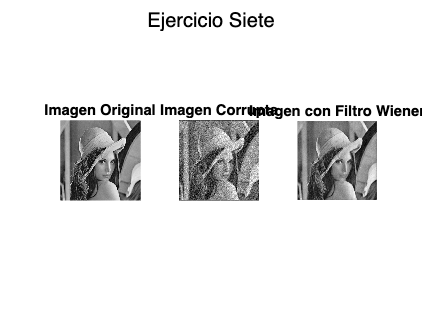

corruptedImage = applyWeightedAverage(originalLenna,9);
corruptedImage = imnoise(uint8(corruptedImage),'gaussian');
results06 = cell(1, 3);
results06{1,1} = originalLenna;
results06{1,2} = corruptedImage;
results06{1,3} = wiener(originalLenna,corruptedImage,4);
showMultipleImages('Ejercicio Siete',results06,{'Imagen Original', 'Imagen Corrupta', 'Imagen con Filtro Wiener'});

### Funciones

#### Filtro Mediana Aritmetico y Geométrico

function newImage = applyMedianFilter(image, filterSize, filterType)
    [n, m] = size(image);
    newImage = zeros(n, m);
    r = n - filterSize + 1; 
    c = m - filterSize + 1;
    halfFilter = floor(filterSize/2);
    for i = 1:r
    for j = 1:c 
        submatrix = image(i:i+filterSize-1, j:j+filterSize-1);
        if strcmpi(filterType, 'aritmetico')
            newImage(i+halfFilter,j+halfFilter) = median(submatrix(:));
        elseif strcmpi(filterType, 'geometrico')
            newImage(i+halfFilter,j+halfFilter) = prod(nonzeros(submatrix(:)))^(1/(filterSize*filterSize));
        elseif strcmpi(filterType, 'adaptativo')
            local_mean = mean(submatrix(:));
            local_var = var(double(submatrix(:)));
            newImage(i+halfFilter,j+halfFilter) = image(i+halfFilter,j+halfFilter) - (0.04 / local_var) * (image(i+halfFilter,j+halfFilter) - local_mean);
        end
    end
    end
end


#### Filtro Mediana Adaptativo

function resultImage = adaptiveFilter(image, smax)
    image = double(image);
    [xb, yb] = size(image);
    imageTemp = zeros(xb, yb);
    
    startPoint = smax - floor(smax/2);
    
    for i = startPoint : startPoint + (xb-1) - smax
        for j = startPoint : startPoint + (yb-1) - smax
            imageTemp(i, j) = getNewValue(image, 3, smax, i, j);
        end
    end
    
    resultImage = imageTemp;
end

function result = getNewValue(image, filterSize, smax, i, j)
    padding = ceil((filterSize-1)/2);
    sub = image(i-padding:i+padding, j-padding:j+padding);
    sortedSub = sort(sub(:));
    
    Zmin = sortedSub(1);
    Zmax = sortedSub(end);
    Zmed = median(sortedSub);
    Zxy = image(i, j);
    
    B1 = Zxy - Zmin;
    B2 = Zxy - Zmax;
    
    if (B1 > 0 && B2 < 0)
        result = Zxy;
        return;
    else
        A1 = Zmed - Zmin;
        A2 = Zmed - Zmax;
        
        if (A1 > 0 && A2 < 0)
            result = Zmed;
            return;
        else
            if (filterSize < smax)
                filterSize = filterSize + 2;
                result = getNewValue(image, filterSize, smax, i, j);
                return;
            else
                result = Zmed;
            end
        end
    end
end

#### Filtro Wiener

function resultImage = wiener(originalImage, noisyImage, caseValue)
    r = originalImage - noisyImage;

    F_original = fft2(originalImage);
    F_noisy = fft2(noisyImage); 
    F_r = fft2(r);
    
    PSD_original = abs(F_original); 
    PSD_noisy = abs(F_noisy); 
    PSD_r = abs(F_r);

    switch caseValue
        case 1
            W = PSD_original./ (PSD_original + PSD_r);
            G = W.*F_noisy;
        case 2
            H = F_noisy./ F_original;
            W = 1./H;
            G = W.*F_noisy;
        case 3
            W = PSD_original./ (PSD_original+PSD_noisy);
            H = F_noisy./ F_original;
            W2 = 1./ H;
            W3 = W.*W2;
            G = W3.*F_noisy;
        case 4
            H = F_noisy ./ F_original;
            H_star = conj(H);
            W = (PSD_original .* H_star) ./ (H .* PSD_original .* H_star + PSD_r);
            G = W .* F_noisy;
    end 
    resultImage = (real(ifft2(G)));
end

#### Filtro Promedio Ponerado

function newImage = applyWeightedAverage(image, filterSize)
    [n, m] = size(image);
    newImage = zeros(n, m);
    r = n - filterSize + 1; 
    c = m - filterSize + 1;
    halfFilter = floor(filterSize/2);
    gaussianFilter = creatGaussianFilter(filterSize);

    for i = 1:r
    for j = 1:c 
        submatrix = image(i:i+filterSize-1, j:j+filterSize-1);
        submatrix = double(submatrix).*gaussianFilter;
        newImage(i+halfFilter,j+halfFilter) = sum(submatrix(:));
    end
    end
end

#### Filtro Gaussiano

function gaussianFilter = creatGaussianFilter(n)
    gaussianFilter = zeros(n, n);
    center = (n+1)/2;    % Se asume que los valores son impares
    sigma = n / 6;       % Desviación

    for i = 1:n
        for j = 1:n
            x = i - center;
            y = j - center;
            gaussianFilter(i, j) = exp(-(x^2 + y^2) / (2 * sigma^2)) / (2 * pi * sigma^2);
        end
    end
    gaussianFilter = double(gaussianFilter) / sum(gaussianFilter(:)); % La suma siempre debe ser uno, este se normaliza
end

#### showMultipleImages

Dada una celda de imágenes y un conjunto de etiquetas, estas se presentan en una nueva ventana. 

function showMultipleImages(figure_title, images, image_labels)
    m = length(images);
    figure;
    for i = 1:m
        subplot(1, m, i);
        imshow(images{i},[]);
        title(image_labels{i});
    end
    sgtitle(figure_title); 
end